# Set Based Estimator Testing

## Setup

clear
close all

#### Simulation Settings

tf = 1;
dt = 0.1;
tspan = 0:dt:tf;

Input

omegaInput = 5;
inputFunction = @(t) sin(omegaInput * t);
U = inputFunction(tspan);

#### System Setup

sysType = "simpleDTsys"; %"springMassDamper" "simpleDTsys"

switch sysType
    case {"springMassDamper"}

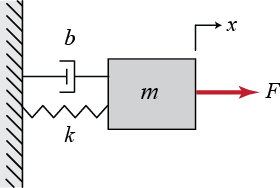

        m = 1;
        k = 1;
        b = 1;
        A_ct = [0, 1; 
            -k/m, -b/m];
        B_ct = [0;
            -1/m];
        C = [1, 0];
        D = [0];
        sys_ct = ss(A_ct,B_ct,C,D)

        A = expm(A_ct * dt);
        B = A * B_ct; %assume small and just disturbance anyway
        sys = ss(A,B,C,D,dt);

    case {"simpleDTsys"}
%         A = diag([0.5 -0.5])
%         * [
%             0.9371    0.8491
%             0.8295    0.3725];
%         A = [
%             0.5 -0.5;
%             -0.5 -0.5]
        A = 0.7 .* [
            1   -1
            1   1
            ];
        B = [
            1 
            0];
        C = eye(2);
        D = ones(2,1);
end
 [numStates, numInputs] = size(B);
 numOutputs = size(C,1);

#### Estimator Setup

Nominal


$$\hat{x}_k = (A + LC) \hat{x}_{k-1} + B u_{k-1} + Ly_{k-1}$$


lambda_obsv = [-1, -1.5];
L = place(A',C',lambda_obsv).';

## Simulation

% Setup
x_0 = 10 * rand(2,1);
x_hat_0 = x_0 + 0.1 * rand(2,1);

% Initialization
x = x_0;
x_hat = x_hat_0;

% Evolution
for k = 1:length(tspan)
    % Inputs and Measurements
    u = U(:,k);
    y = C * x + D * u;
    y_hat = C * x_hat;

    % State Equations
%     dx = A * x + B * u;
%     dx_hat = A * x_hat + B * u + L*(y - y_hat);
    
    % Euler Update
%     x = x + dx * dt;
%     x_hat = x_hat + dx_hat * dt;
    x = A * x + B * u;
    x_hat = A * x_hat + B * u + L * (y - y_hat);
    
    % Store Values
%     X_data(:,k) = x;
%     X_hat_data(:,k) = x_hat;
%     Y_data(:,k) = y;
%     Y_hat_data(:,k) = y_hat;
end

## Set Based

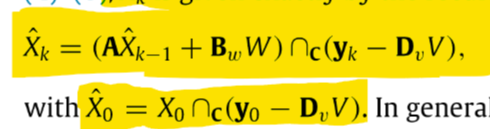

assume that essentially the bound is what we call the x_hat... (the idea of enclosue vs exact definition)

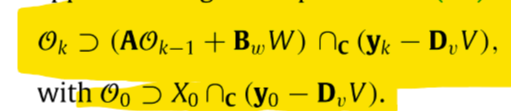

the intersection definition (using the generalizedIntersection() function adds a constraint demension each timestep:

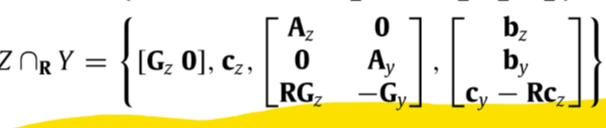

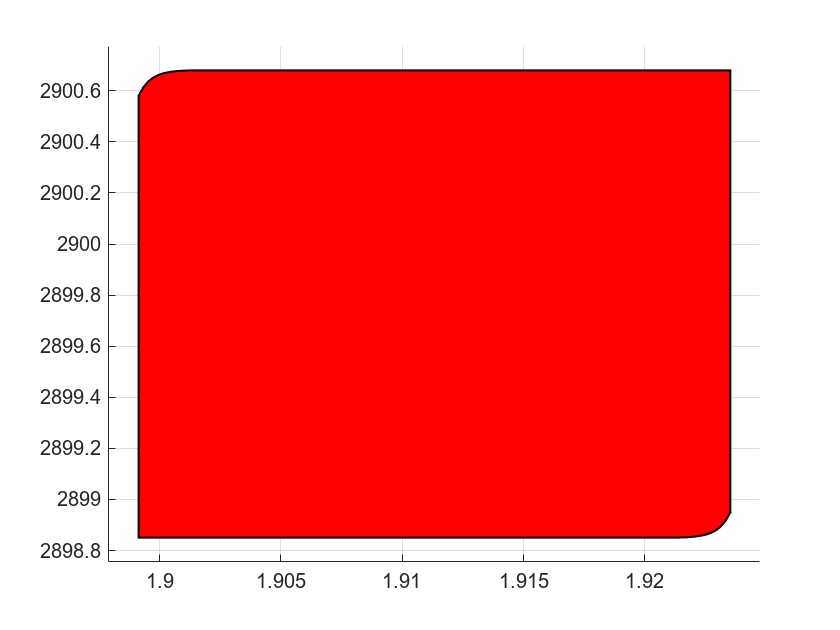

% error bound scale
w_0 = 0.0001;
v_0 = 0.0001 .* ones(numInputs,1);
x_hat_0_error = 0.01;

% error zonotopes
W_0 = conZono(0, w_0, [], []);
V_0 = conZono(zeros(size(numOutputs,1)), v_0, [], []);
X_hat_0 = conZono(x_hat, x_hat_0_error * eye(size(x_0,1)), [], []);

% plot setup
% fig = figure;
% ax = axes;

% Evolution
x = x_0;
x_hat = x_0 .* (1 + 0.1 * (2*rand(size(x_0))-1));
X_hat = X_hat_0;
W = W_0;
V = V_0;
for k = 1:length(tspan)
    % Inputs and Measurements
    u = w_0 .* (2 * rand(size(w_0)) - 1);
    y = C * x + D * u + v_0 .* (2 * rand(size(v_0)) - 1);
    
    % System Evolution
    x = A * x + B * u;
    X_hat = (A - L*C) * X_hat + B * W + L * (-D * V + y);
%     X_hat = generalizedIntersection(A * X_hat + B * W, (-D * V + y), C);

    % Save Data
    X_data(:,k) = x;
    Y_data(:,k) = y;
    U_data(:,k) = u;
    X_hat_data(k) = X_hat;
    
    

    % Plot
%     hold off
%     figure
    X_hat.plot
%     axis([-500 500 -500 500])
%     hold on
%     plot(x(2),x(1))
%     axis([-1 1 -1 1])
    M(k) = getframe(gcf);
%     close gcf
end

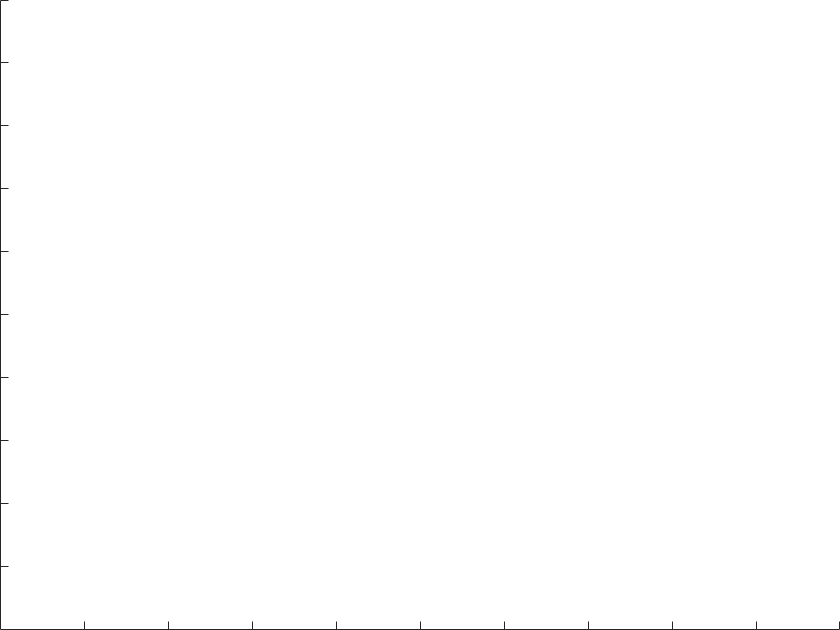

figure
axes("Position",[0 0 1 1])

movie(M,1,2)

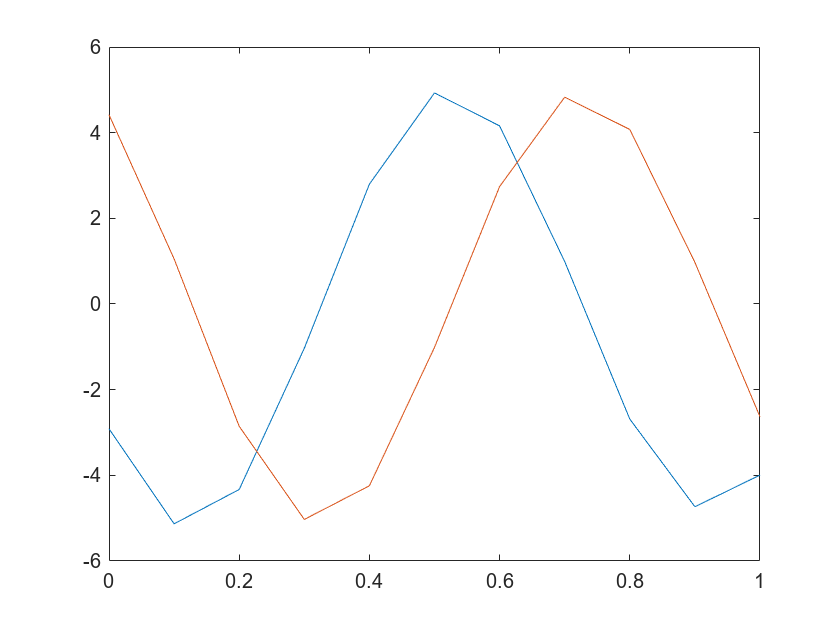

figure
title('actual values')
plot([tspan' tspan'], X_data')

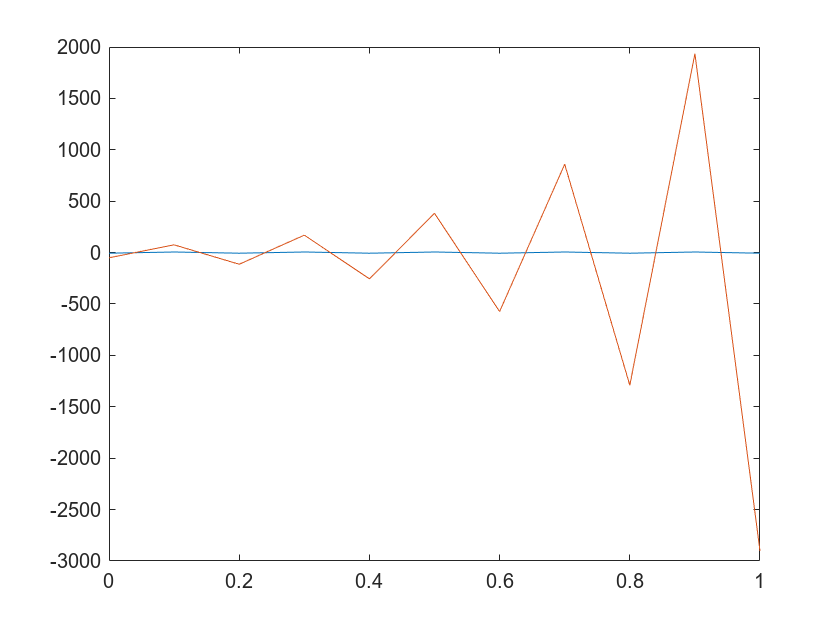

figure
% X_hat_data_c = [X_hat_data.c]
title('error')
plot([tspan' tspan'], X_data' - [X_hat_data.c]')

## test

X_hat_0

X_hat_0 =   conZono with properties:

        c: [2×1 double]
        G: [2×2 double]
        A: [0×2 double]
        b: []
        n: 2
       nG: 2
       nC: 0
    order: 1


X_hat_0.c

ans =    -4.8303
  -28.3186


X_hat_0.G

ans =     0.0100         0
         0    0.0100


X_hat_0.A


ans =

  0×2 empty double matrix



X_hat_0.b


ans =

     []



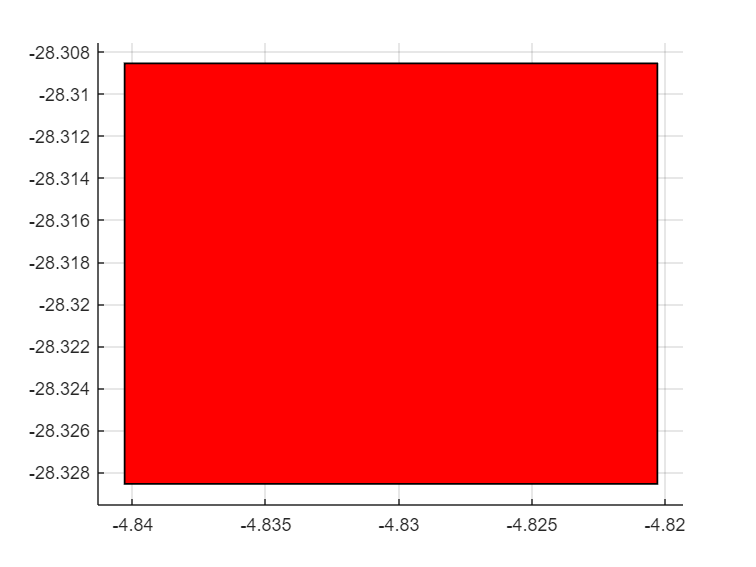

X_hat_0.plot

X_hat_data(1)

ans =   conZono with properties:

        c: [2×1 double]
        G: [2×4 double]
        A: [0×4 double]
        b: []
        n: 2
       nG: 4
       nC: 0
    order: 2


X_hat_data(1).c

ans =     2.9917
   54.7505


X_hat_data(1).G

ans =    -0.0100         0    0.0001   -0.0001
         0   -0.0150         0   -0.0003


X_hat_data(1).A


ans =

  0×4 empty double matrix



X_hat_data(1).b


ans =

     []



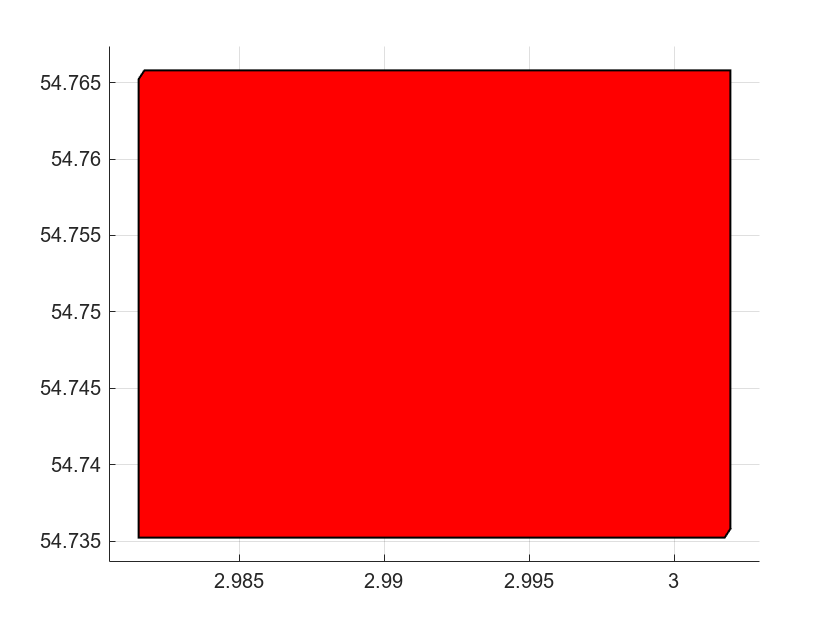

X_hat_data(1).plot